# **Demo1: Rule-based trading**

Copyright 2018 The MathWorks, Inc.

In this demo, we will use 14-day RSI to create a trading strategies and backtested using both in-sample and out-of-sample. The position is assumed to open at the end of the day in whcih signal is created and close in the end of next trading day.

## **Setup**

clear
clc
load data3_demo1.mat
tDay = 252; % number of trading day per annum

## Create rule-based signal and backtest (In-sample)

For signal creation, buy if 14-day RSI < 30 (over-sold) and sell if 14-day RSI >70 (over-bought).

signal1 = 1*(inSample.rsi14 < 30) - 1*(inSample.rsi14 > 70);
portReturns1 = signal1(1:end-1).*inSample.ret1(2:end,:);
portValue1 = ret2tick(portReturns1);
sharpeRatio1 = sharpe(portReturns1,0)*sqrt(tDay)

sharpeRatio1 = 0.7378

Visualize the equity curve wtih initial portfolio value of 1.

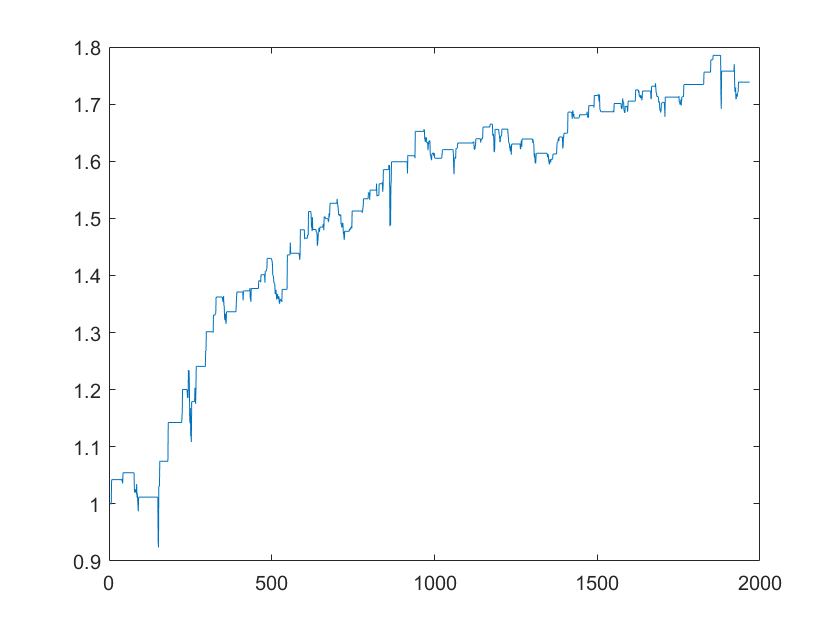

figure
plot(portValue1)
savefig('plotInSample_Demo1.fig');

## Create rule-based signal and backtest (Out-of-sample)

For signal creation, buy if 14-day RSI < 30 (over-sold) and sell if 14-day RSI >70 (over-bought).

signal2 = 1*(outSample.rsi14 < 30) - 1*(outSample.rsi14 > 70);
portReturns2 = signal2(1:end-1).*outSample.ret1(2:end,:);
portValue2 = ret2tick(portReturns2);
sharpeRatio2 = sharpe(portReturns2,0)*sqrt(tDay)

sharpeRatio2 = 0.0484

Visualize the equity curve wtih initial portfolio value of 1.

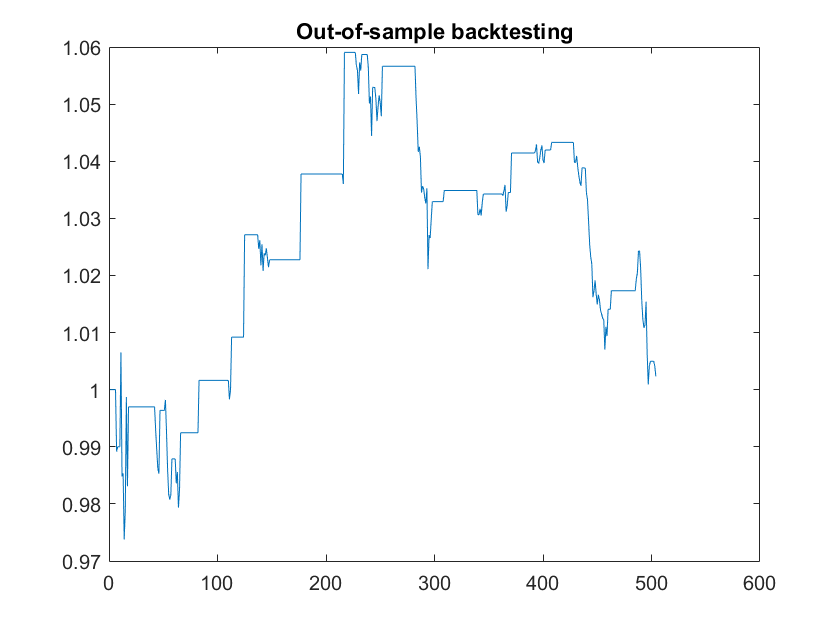

plot(portValue2)
title('Out-of-sample backtesting')
savefig('plotOutSample_Demo1.fig');